I am going to try to calculate volume using regionprops3.

Therefore I need a meshgrid, but I only have a pointcloud (sie ply_planefit)

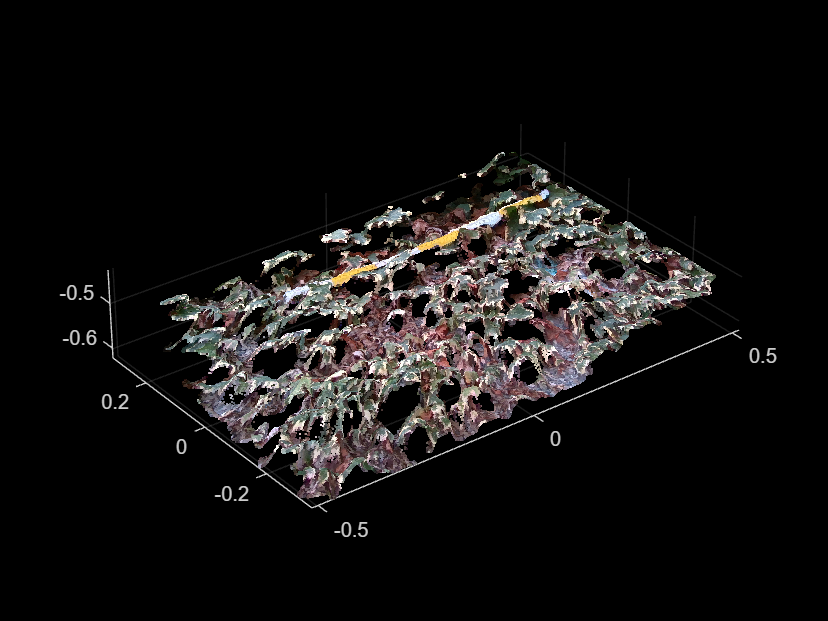

clear
close all
pointcloud = pcread('..\..\PLY files\LC_20231130_145915.ply');
%clean up the pointcloud by setting the distance to an overestimation of the approximate distance to the wall
% such that only actual outliers are removed
[model,inlierIndices, outlierIndices] = pcfitplane(pointcloud,1);
cleancloud = select(pointcloud, inlierIndices);
pcshow(cleancloud)

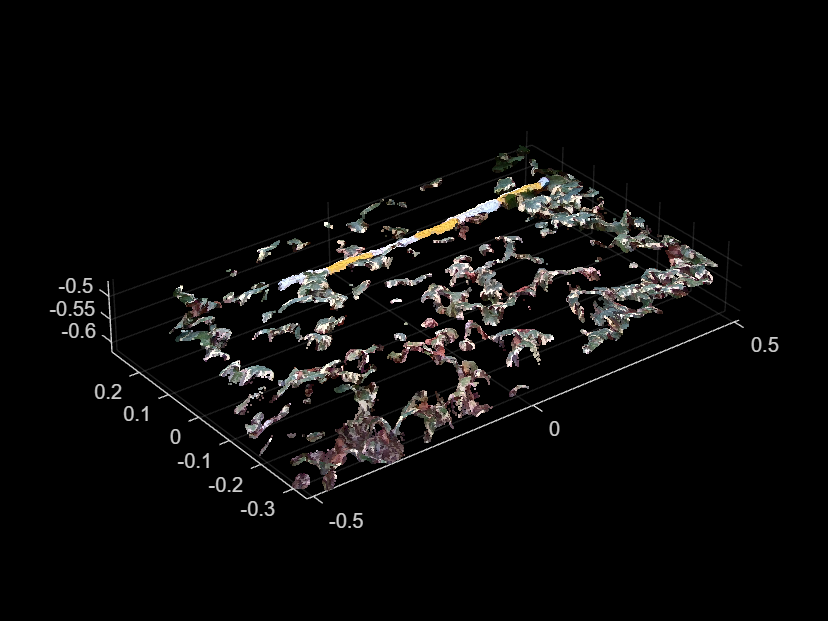


estimatedLayerThickness = 0.01;
[model,inlierIndices, outlierIndices] = pcfitplane(cleancloud,estimatedLayerThickness);
firstlayer = select(cleancloud, inlierIndices);
figure();pcshow(firstlayer)

Convert pointcloud to meshgrid:

`[`[`mesh`](https://nl.mathworks.com/help/lidar/ref/pc2surfacemesh.html#mw_27080a94-9c00-4f76-96fc-cf1bd0e43a1c)`,`[`depth`](https://nl.mathworks.com/help/lidar/ref/pc2surfacemesh.html#mw_0906f2cf-75cc-49ba-8f4b-ab9cba0b4589)`,`[`perVertexDensity`](https://nl.mathworks.com/help/lidar/ref/pc2surfacemesh.html#mw_63252b9d-dbf6-428f-b7f4-2d30b4179f23)`] = pc2surfacemesh(`[`ptCloudIn`](https://nl.mathworks.com/help/lidar/ref/pc2surfacemesh.html#mw_2819fdbc-4ec4-4de2-8878-fccd062c5eca)`,"poisson")` creates a surface mesh from the input point cloud `ptCloudIn` using the Poisson reconstruction method. The function also returns the octree depth used in the reconstruction `depth` and the vertex density `perVertexDensity`.

[mesh,depth,vertex] = pc2surfacemesh(cleancloud,"poisson"); % INSTALL Lidar toolbox

[WARNING] B:\3p\install\9807001\win64\poissonrecon\include\PoissonRecon\Src\FEMTree.Initialize.inl (Line 193)
          FEMTreeInitializer<3,float>::Initialize
          Found bad data: 1507


Showing the mesh

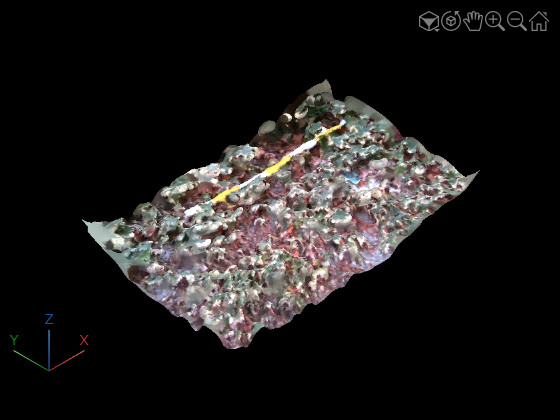

surfaceMeshShow(mesh)

Extracting x,y,z out of the mesh:

vertices = mesh.Vertices;
x = vertices(:,1);
y = vertices(:,2);
z = vertices(:,3);

Doing random things because it is in Matlab help:

[https://nl.mathworks.com/help/images/ref/regionprops3.html?searchHighlight=regionprops3&s_tid=srchtitle_support_results_1_regionprops3](https://nl.mathworks.com/help/images/ref/regionprops3.html?searchHighlight=regionprops3&s_tid=srchtitle_support_results_1_regionprops3)

bw1 = x < 5;
%bw2 = sqrt((x-20).^2 + (y-30).^2 + (z-15).^2) < 10;
bw = bw1; %| bw2;

D_volume = regionprops3(bw, 'Volume');
